**Experiment - 5                                                                                 Date - 23/2/2024**

**Aim :- Design simple filters using Z - Transform and Pole - Zero Analysis**

**Laboratory Exercise **

A) Evaluate the following z - transform on the unit circle :

**                                G (z) = 2 + 5z-1 + 9z-2 + 5z-3 + 3z-4 / 5 + 45z-1 + 2z-2 + z-3 + z-4    **- (1)

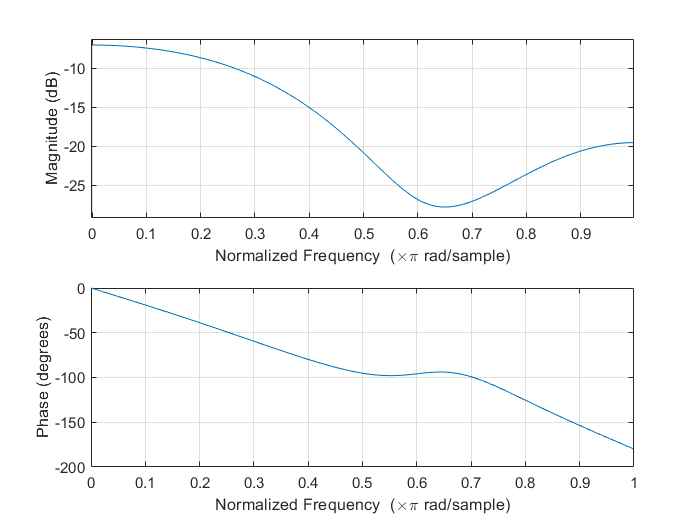

clc ; clear all ; close all ; 

b = [2 , 5 , 9 , 5 , 3] ; a = [5 , 45 , 2 , 1 , 1] ;
freqz(b,a); % Frequency Response 

**Comment :- **Here , the type of response looks similar to a the response of a Low Pass , but it is not a perfect or ideal LPF response and to achieve ideal LPF response we need to design a higher order Filter .

B) Write a program to compute and display the poles and zeros using **zplane() **, to compute and display the factored form , and to generate the pole - zero plot of given transfer function in Eq. (1).

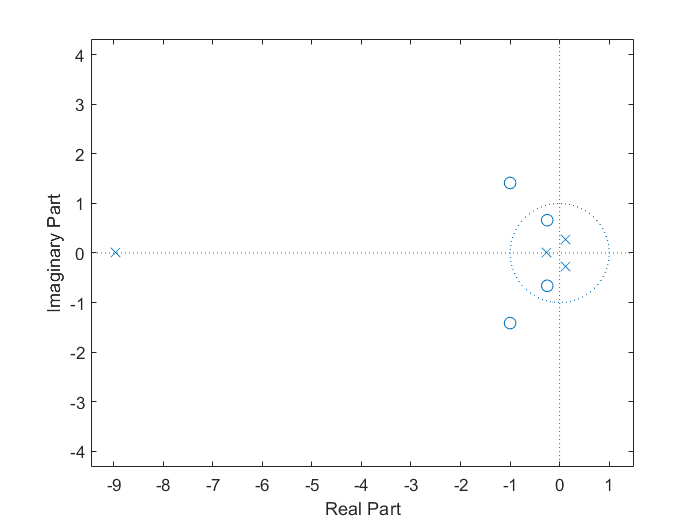

clc ; clear all ; close all ; 
b = [2 , 5 , 9 , 5 , 3] ; a = [5 , 45 , 2 , 1 , 1] ;

%Plots poles and zeros 
zplane(b,a);

[z,p,k] = tf2zp(b,a) ;

fprintf("The value of zeros , poles and gain respectively are :- ") ;

The value of zeros , poles and gain respectively are :- 

disp(z) ; disp(p) ; disp(k) ;

  -1.0000 + 1.4142i
  -1.0000 - 1.4142i
  -0.2500 + 0.6614i
  -0.2500 - 0.6614i

  -8.9576 + 0.0000i
  -0.2718 + 0.0000i
   0.1147 + 0.2627i
   0.1147 - 0.2627i

    0.4000




[b,a] = zp2tf(z,p,k) ;
fprintf("The values of b and a respectively are :- ") ;

The values of b and a respectively are :- 

disp(b) ; disp(a) ;

    0.4000    1.0000    1.8000    1.0000    0.6000

    1.0000    9.0000    0.4000    0.2000    0.2000



**Comment :- ** From above figure we can say that the given system is unstable as two zeroes are lying outside unit circle . In this question , we learnt to use the functions tf2zp() and zp2tf() , which are used to get location of poles , zeros and gain of the filter .

C) Design a 1st order IIR lowpass and a 1st order IIR highpass filter with a 3-dB angular cutoff frequency Wc at 0.45pi . Using MATLAB compute and plot their gain responses , and verify that designed filters meet the specification . Refer the following equations for designing IIR Filters . 

                                                                Hlp(z) = (1 - a / 2) 1 + z^-1 / 1 - az^-1                  -(2)

                                                                Hhp(z)  = (1 + a / 2)  1 - z^-1 / 1 - az^-1               -(3)

where , a = 1 - sinWc / cosWc

Here , |a| is chosen lesser than unity for stability . Also , Wc denotes 3dB digital cutoff frequency represented in radians .

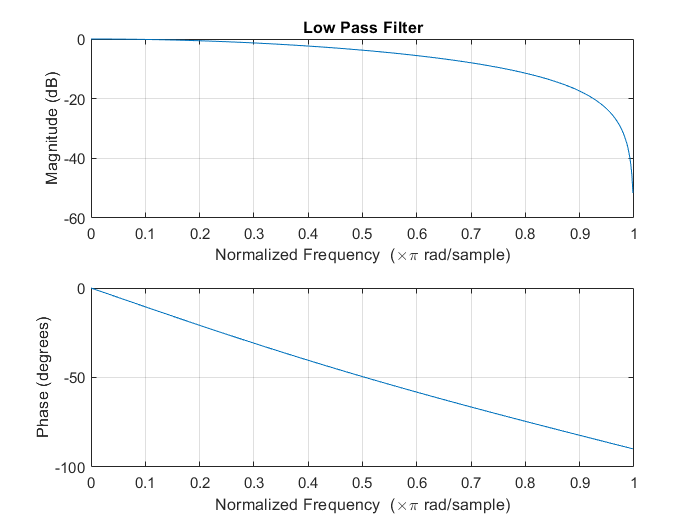

clc ; clear all ; close all ; 
Wc = 0.45 * pi ; alpha = (1 - sin(Wc)) / cos(Wc) ; b1 = [(1 - alpha) / 2 , (1 - alpha) / 2] ; a1 = [1 , -1 * alpha] ;
freqz(b1,a1) ; title("Low Pass Filter") ; 

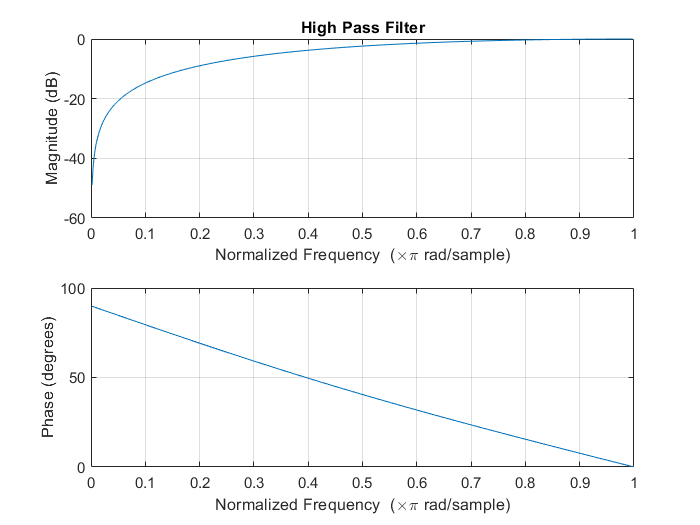


b2 = [(1 + alpha) / 2 , - (1 + alpha) / 2] ; a2 = [1 , -1 * alpha] ;
freqz(b2,a2) ; title("High Pass Filter") ;


fprintf("Value of Alpha :- ") ;

Value of Alpha :- 

disp(alpha) 

    0.0787



**Comment :- **Here , the type of responses looks similar to a the response of a Low Pass and High Pass respectively . These filters are designed using the Tranfer Function given in the question . We also verified the the filter by measuring cutoff frequency by datatips . We got the equation of transfer function for Low and High Pass IIR Filters .

D) Design lowpass IIR Filter with the following specifications using pole - zero placement method :

Filter order = 1 , 3-dB cut-off frequency = 1200Hz , Sampling Rate = 8000Hz . Print the lowpass IIR filter coeffiecients and plot the frequency responses using Matlab . What are the filter gains for the  stopband at the cut - off frequency at 2000Hz , and passband at 100Hz based on the plot of the magnitude frequency response ?

filterDesigner

% function Hd = Filter5D
% %FILTER5D Returns a discrete-time filter object.
% 
% % MATLAB Code
% % Generated by MATLAB(R) 23.2 and Signal Processing Toolbox 23.2.
% % Generated on: 28-Mar-2024 20:07:12
% 
% % Butterworth Lowpass filter designed using FDESIGN.LOWPASS.
% 
% % All frequency values are in Hz.
% Fs = 8000;  % Sampling Frequency
% 
% N  = 1;     % Order
% Fc = 1200;  % Cutoff Frequency
% 
% % Construct an FDESIGN object and call its BUTTER method.
% h  = fdesign.lowpass('N,F3dB', N, Fc, Fs);
% Hd = design(h, 'butter');
% 
% % [EOF] 

filterDesigner


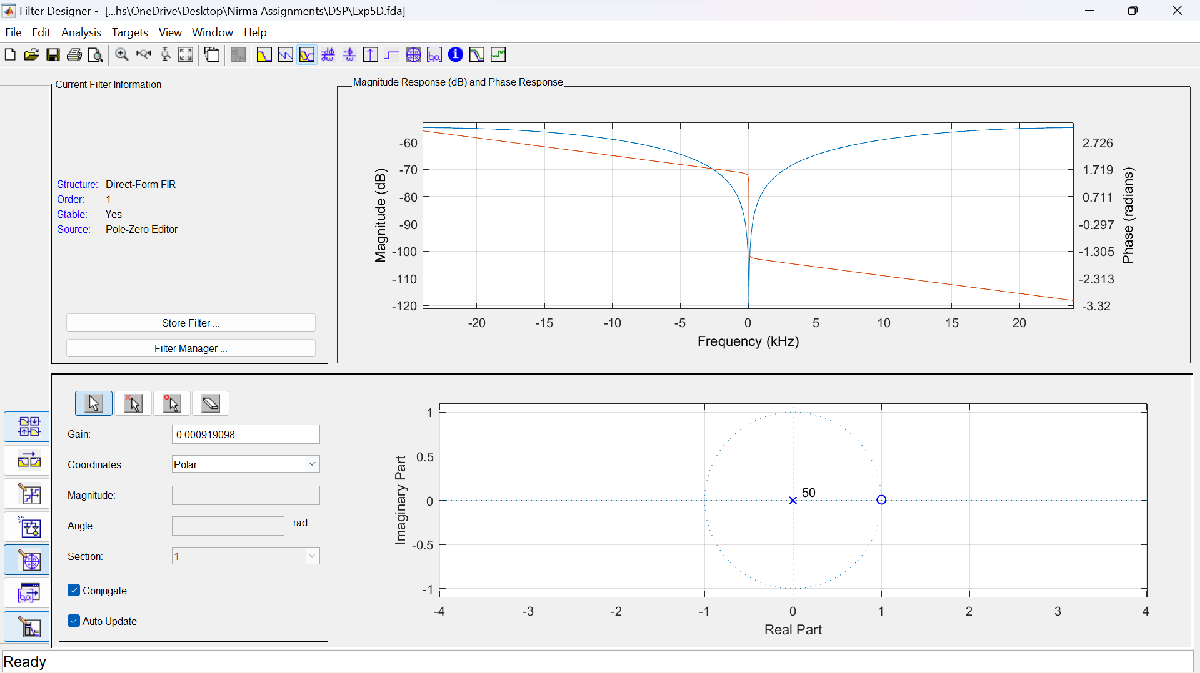

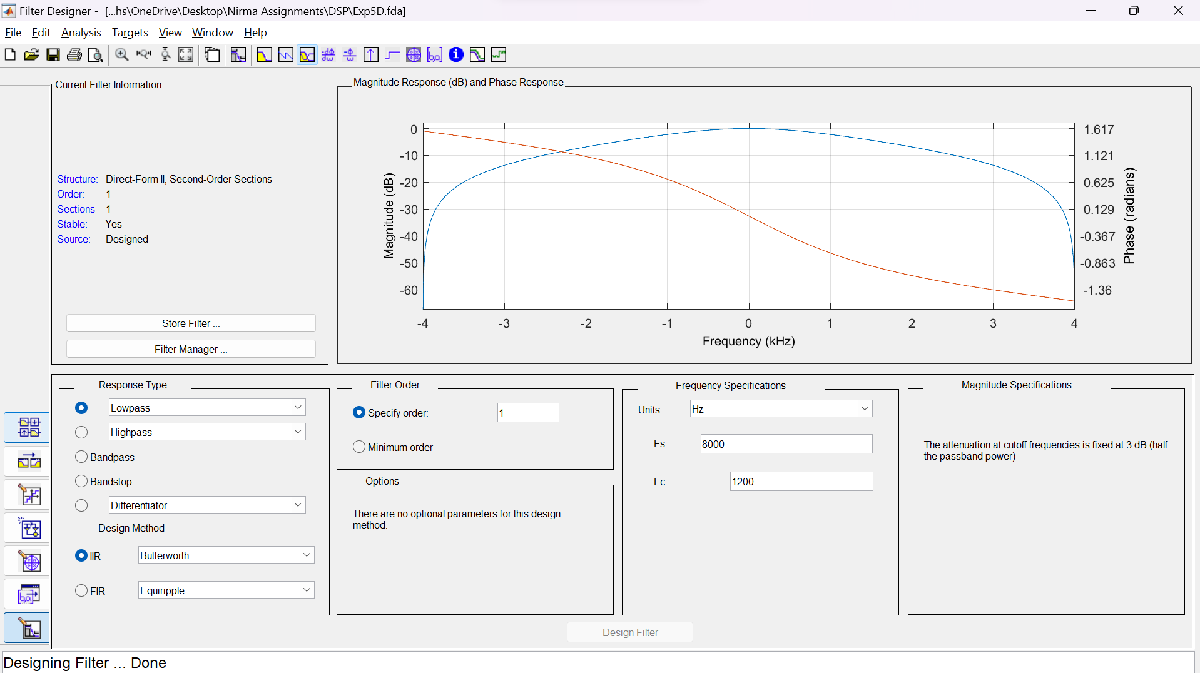

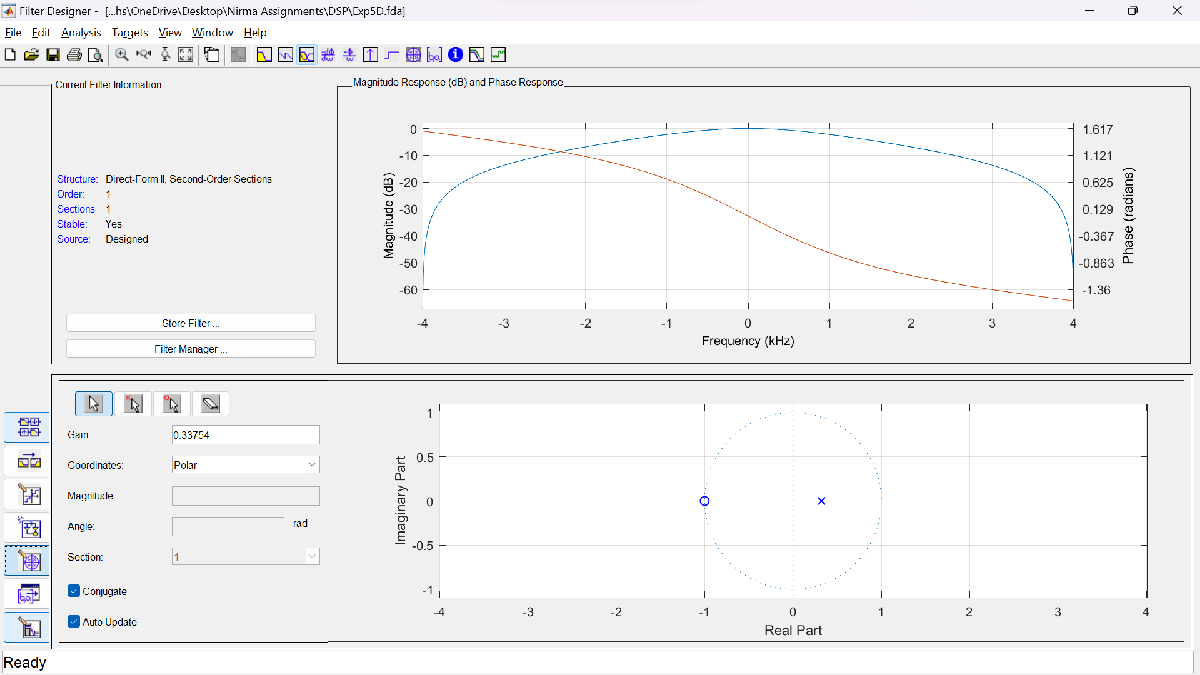

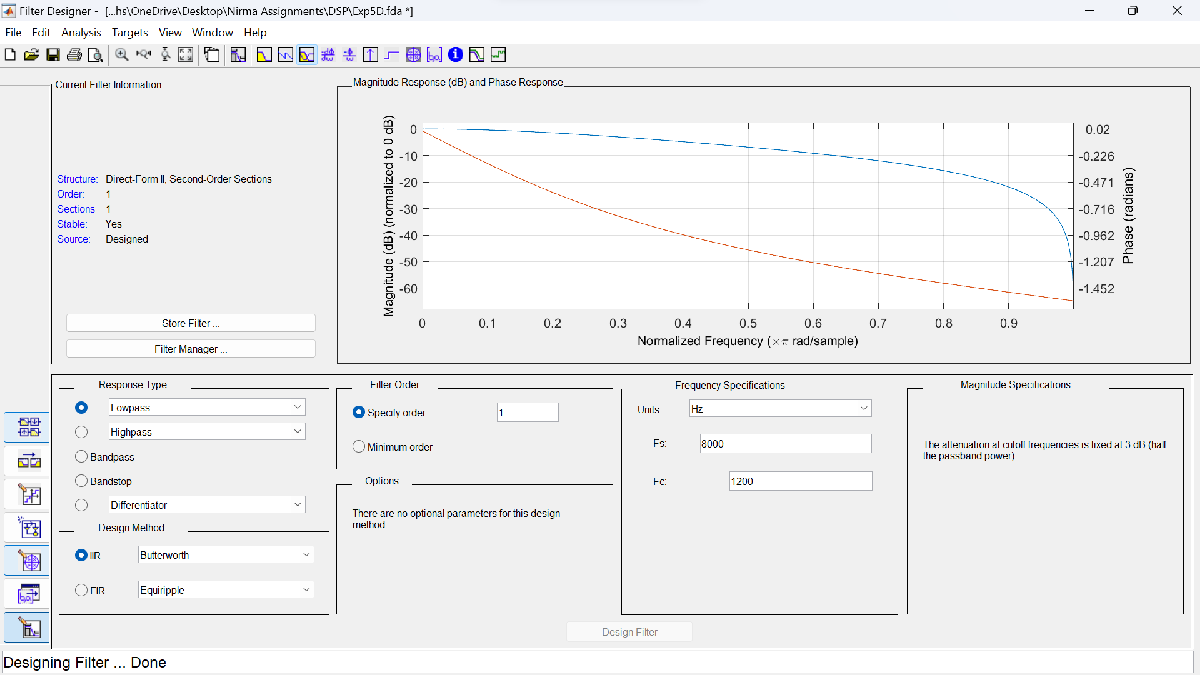

**Comment :- **Here , we learnt to use the filter designer app or function in MATLAB and also how we can design our own filter by setting some of the necessary parameters in the filterdesigner window . We can also generate MATLAB code for the same . 

E) Design a second - order band pass filter with a center frequency w0 at 0.61pi and a 3-dB bandwidth of 0.15pi . Since Eq.(6) is a quadratic equation in 'a' , there will be two values of the parameter 'a' yeilding the same value of the 3-dB bandwidth , resulting in two different expressions for the transfer function Hbp(z) . Using the function zplane , develop the pole - zero plots of the two designs obtained and choose the design that results in a stable transfer function . Using MATLAB compute and plot the gain response of the filter you designed , and verify that it indeed meets the given specifications .

                        Hbp(z) = (1 - a) / 2  * (1 - z ^ -2) / (1 - b (1 + a) z ^ -1 + a z ^ -2)

                        where , w0 = cos-1(b)

                and , Del(w3-dB) = wc2 - wc1 = cos-1(2a / 1 + a^2)                - (6)

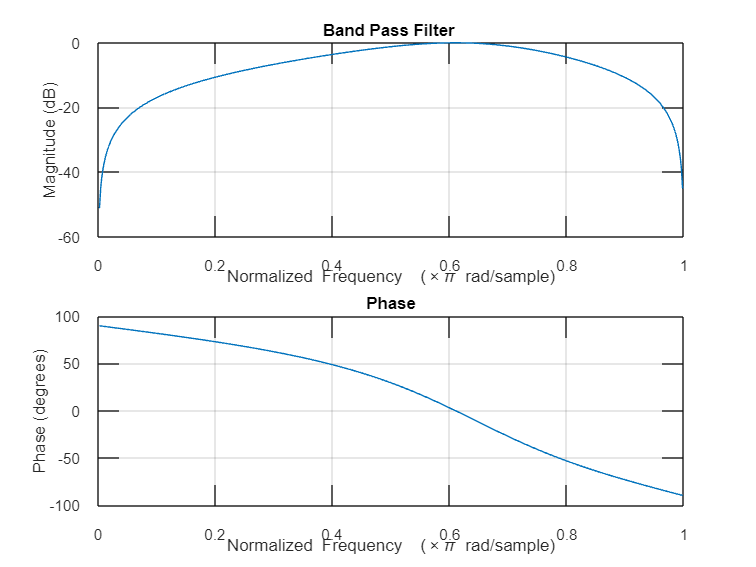

clc ; clear all ; close all ;

w0 = 0.61*pi ; delw = 0.15*pi ;
beta = cos(w0) ; p = [delw -2 delw] ; alpha = roots(p) ;

if (abs(alpha(1)) < 1 && abs(beta) < 1)
    b = [(1-alpha(1))/2 , 0 , -(1-alpha(1))/2] ;
    a = [1 , -beta*(1+alpha(1)) , alpha(1)] ;
elseif (abs(alpha(2)) <  1 && abs(beta) < 1)
    b = [(1-alpha(2))/2 , 0 , -(1-alpha(2))/2] ;
    a = [1 , -beta*(1+alpha(2)) , alpha(2)] ;
end

freqz(b,a) ; grid on ; title("Band Pass Filter ") ;

** Comment :- **Here , the type of responses looks similar to a the response of a Band Pass Filter . This filter is designed using the Tranfer Function given in the question . We also verified the the filter by measuring cutoff frequency by datatips . We got the equation of transfer function for Low and High Pass IIR Filters .

**Conclusion :- Using MATLAB to design simple Filters using Z transform helps us to understand the concept of Z plane and Transfer Function and Pole - Zero analysis helps us to get an idea of what is the effect of poles and zeros on the filter and transfer function .**